close("all"); clear; clc;
setmadsympath();
addpath("prydeMotorcycleStateSpace\");

## Parameters

### Sharp model parameters

Cdelta = 6.77;
Cf1 = 11174;
Cf2 = 938.6;
Cr1 = 15831;
Cr2 = 1325.6;
Ibxx = 31.18;
Ibxz = -1.7355;
Ibzz = 21.07;
Ihxx = 1.2338;
Ihzz = 0.442;
a = 0.9485376;
af0 = 0.02;
an = 0.1158;
ar0 = 0.02;
b = 0.4798;
e = 0.0244;
f = 0.0283;
g = 9.80665;
h = 0.6157;
ify = 0.7186;
iry = 1.0508;
mb = 217.45;
mh = 30.65;
rf = 0.3048;
rr = 0.3048;
tf = 0.025;
tr = 0.025;
caster = 0.4715;

### Center of mass

Ob = [b,0,h].';
Oa = [b,0,0].';
Ry = roty(rad2deg(-caster));
Oh = Oa + Ry*[a,0,0].';
m = mb + mh;
G = (mb.*Ob + mh.*Oh)./m;

### Normal forces

l = (a - an)/cos(caster);
p = b + l;
Zr = m*g*(p - G(3))/p;
Zf = m*g*G(3)/p;

### Tire coefficients

Longitudinal :

kkf = 12;
kkr = 12;

Lateral :

kaf = Cf1/Zf;
klf = Cf2/Zf;
kar = Cr1/Zr;
klr = Cr2/Zr;

### Longitudinal displacement

p = b + (a - an)/cos(caster);
fw0 = 0.0085 + 0.018/p;
fw2 = 1.59E-06/p;

### Pryde parameters

params = @(v)[
    Cdelta;
    Ibxx;
    Ibxz;
    Ibzz;
    Ihxx;
    Ihzz;
    v;
    Zf;
    Zr;
    a;
    af0;
    an;
    ar0;
    b;
    e;
    f;
    fw0;
    fw2;
    g;
    h;
    ify;
    iry;
    kaf;
    kar;
    kkf;
    kkr;
    klf;
    klr;
    mb;
    mh;
    rf;
    rr;
    tf;
    tr;
    caster
    ];

## Model

vx = linspace(30,130,1000).';
f = @(v)plant(params(v));
sys = arrayfun(f,vx./3.6,"uniform",0);

## Root locus

f = @(sys)pole(sys);
poles = cell2mat(cellfun(f,sys,"uniform",0));
re = real(poles);
im = imag(poles);

Plot poles over speed :

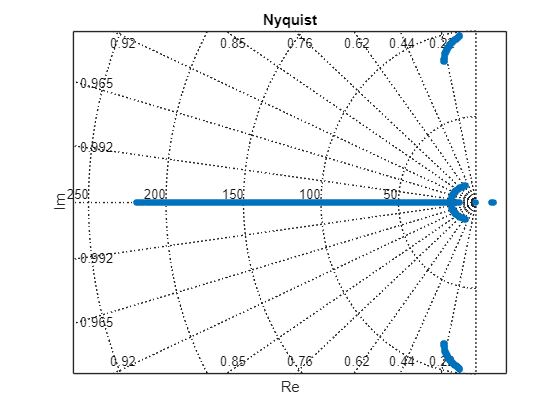

fig = figure();
axe = axes(fig);
scatter(axe,re,im,25,"filled");
xlim(axe,[-260,20]);
xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

ns = 1E06;
t = linspace(0,2,ns);

Rr = rr + tr;
Rf = rf + tf;

x0 = @(v)[
    0;
    0;
    0;
    v;
    0;
    0;
    -v/Rr;
    0;
    -v/Rf
    ];

Plot impulse responses over speed :

titles = [
    "\phi";
    "\delta";
    "\omega_z";
    "v_x";
    "v_y";
    "\omega_x";
    "\omega_r";
    "\omega_\delta";
    "\omega_f"
    ];

fig = figure();
tiledlayout(3,3);


mblue = "#0072BD";

cfg = RespConfig( ...
    "InitialState",x0(130) ...
    );

m = sys{end};
sys0 = ss(m.A,m.B(:,2),m.c,m.D(:,2));
% initial(sys0,cfg)

rmpath("prydeMotorcycleStateSpace\")

function sys = plant(params)
    arguments
        params (35,1) double;
    end
    sys = prydeMotorcycleStateSpace(params);

    sys.StateName = [
        "phi";
        "delta";
        "omega_bz";
        "v_rx";
        "v_ry";
        "omega_bx";
        "omega_r";
        "omega_delta";
        "omega_f"
        ];
    
    sys.InputName = [
        "tau_r";
        "tau_delta"
        ];
    
    sys.OutputName = sys.StateName;
end